clear; clc; close all;
%% 1) LOAD DATA
% MATLAB's Deep Learning Toolbox ships two small helper functions,
% digitTrain4DArrayData and digitTest4DArrayData, that handle loading
% the 10,000-image digit dataset (0-9) for you -- no manual file paths,
% no zip extraction needed. This avoids all path/download issues.
[XTrainImgs, YTrainCat] = digitTrain4DArrayData;   % 28x28x1xN images + categorical labels
[XTestImgs,  YTestCat]  = digitTest4DArrayData;
numTrain = size(XTrainImgs, 4);
numTest  = size(XTestImgs, 4);
fprintf('Loaded %d training images and %d test images.\n', numTrain, numTest);

Loaded 5000 training images and 5000 test images.


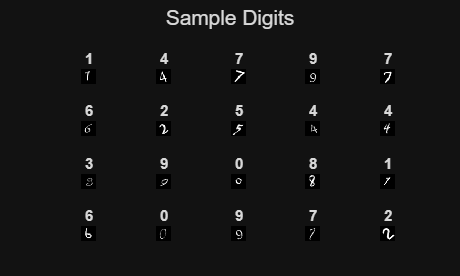

% Quick look at a few sample images
figure;
perm = randperm(numTrain, 20);
for i = 1:20
    subplot(4,5,i);
    imshow(XTrainImgs(:,:,:,perm(i)));
    title(char(YTrainCat(perm(i))));
end
sgtitle('Sample Digits');

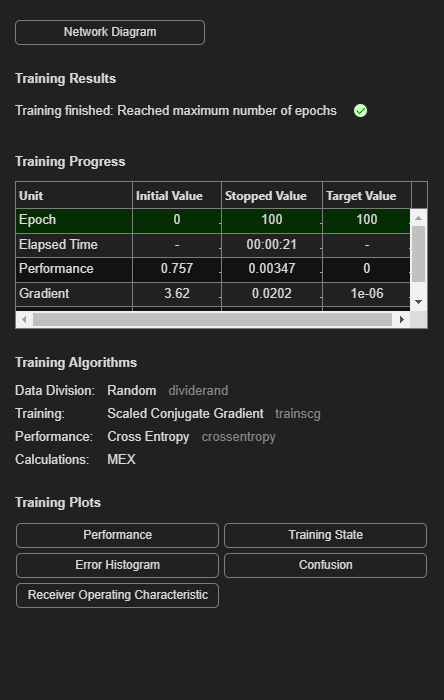


%% 2) CONVERT IMAGES TO FEATURE VECTORS (flatten pixels)
% Each 28x28 image becomes a 784x1 input vector.

XTrain = reshape(XTrainImgs, 28*28, numTrain);   % 784 x numTrain
XTrain = double(XTrain) / 255;                    % normalize to [0,1]
XTest = reshape(XTestImgs, 28*28, numTest);
XTest = double(XTest) / 255;
YTrain = double(YTrainCat);   % class indices 1..10 (10 = digit 0)
YTest  = double(YTestCat);
% One-hot encode labels for the ANN (10 output neurons)
YTrainOH = full(ind2vec(YTrain'));
YTestOH  = full(ind2vec(YTest'));

%% 3) BUILD A SIMPLE FEEDFORWARD ANN
% Input(784) -> Hidden(128) -> Hidden(64) -> Output(10)
hiddenLayer1Size = 128;
hiddenLayer2Size = 64;
net = patternnet([hiddenLayer1Size hiddenLayer2Size]);
% Split train/val/test internally handled by the toolbox
net.divideParam.trainRatio = 0.85;
net.divideParam.valRatio   = 0.15;
net.divideParam.testRatio  = 0;
net.trainParam.epochs = 100;
net.trainParam.showWindow = true;   % set false to hide training GUI

%% 4) TRAIN THE NETWORK
[net, tr] = train(net, XTrain, YTrainOH);


%% 5) EVALUATE ON TEST SET
YPredOH = net(XTest);
YPred = vec2ind(YPredOH);   % predicted class indices (1..10)
accuracy = mean(YPred(:) == YTest(:)) * 100;
fprintf('Test Accuracy: %.2f%%\n', accuracy);

Test Accuracy: 95.98%


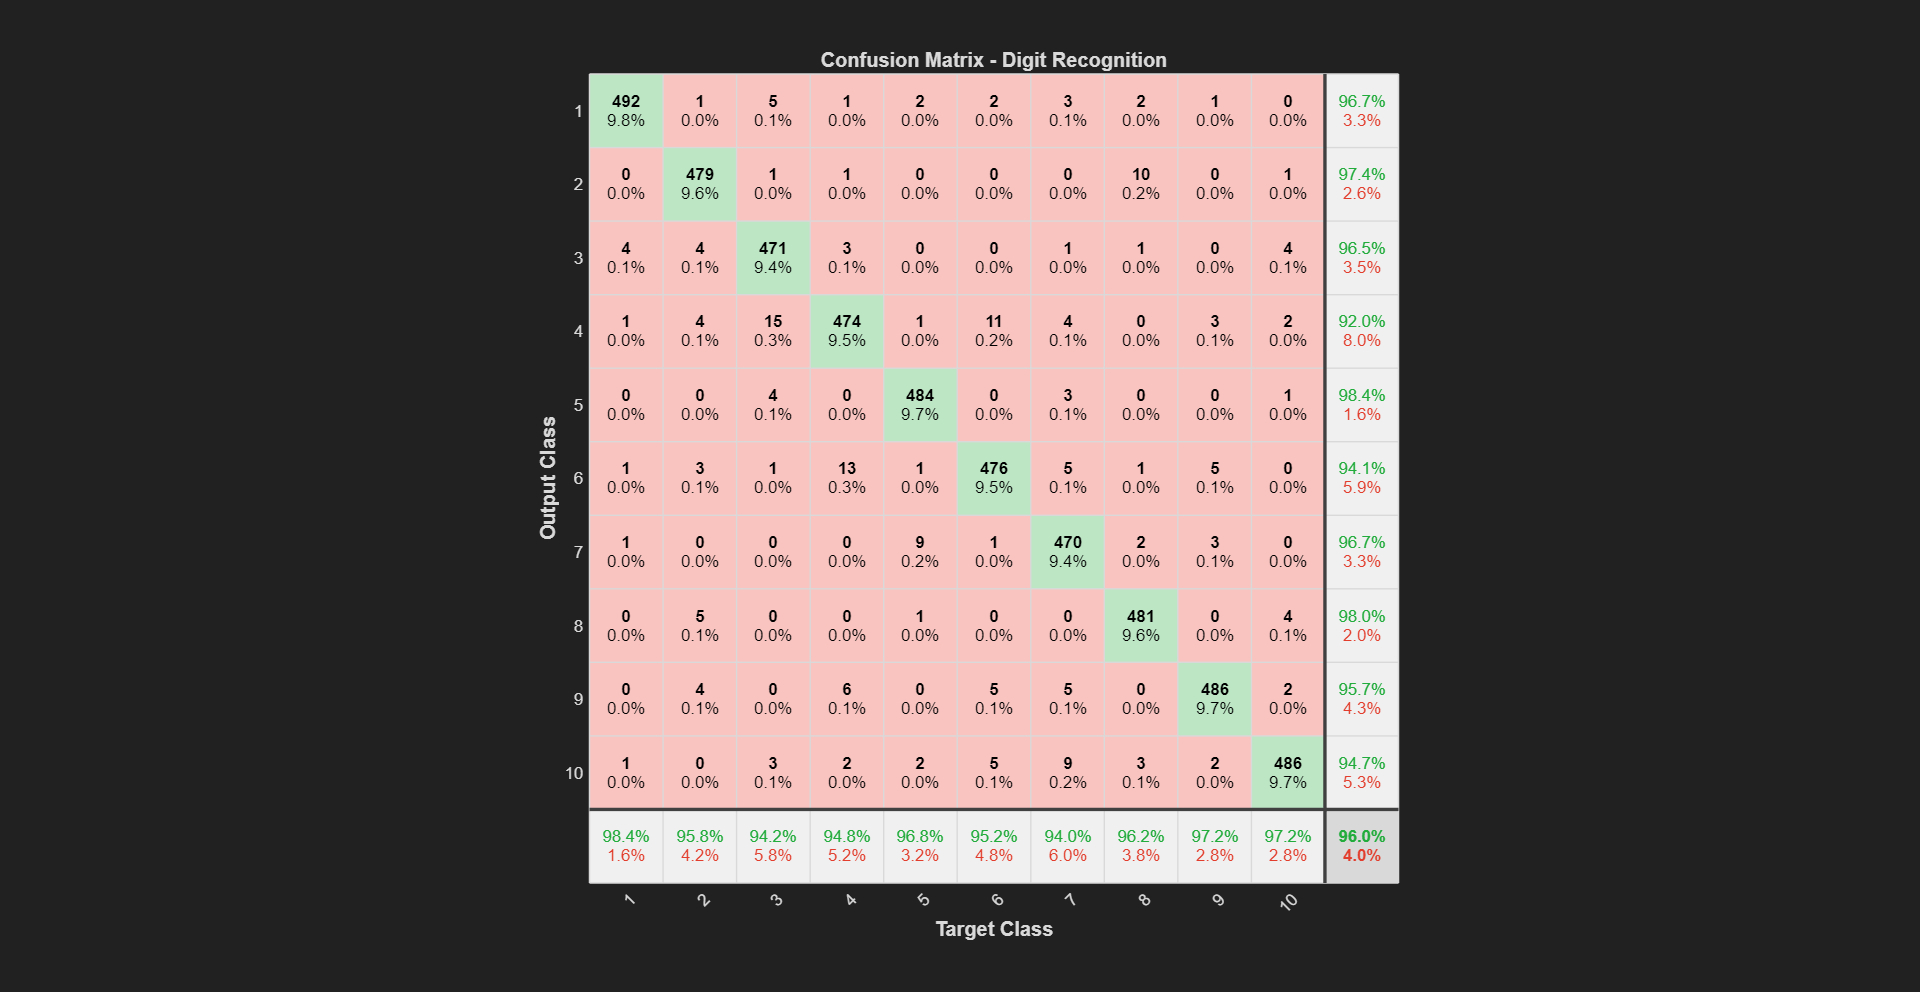


%% 6) CONFUSION MATRIX
figure;
plotconfusion(YTestOH, YPredOH);
title('Confusion Matrix - Digit Recognition');

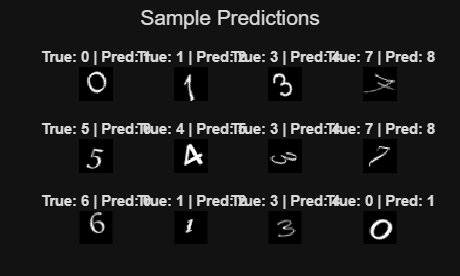


%% 7) VISUALIZE A FEW PREDICTIONS
figure;
sampleIdx = randperm(numTest, 12);
for i = 1:12
    subplot(3,4,i);
    imshow(XTestImgs(:,:,:,sampleIdx(i)));
    trueLabel = char(YTestCat(sampleIdx(i)));
    predLabel = num2str(mod(YPred(sampleIdx(i)), 10)); % map 10->0
    title(sprintf('True: %s | Pred: %s', trueLabel, predLabel));
end
sgtitle('Sample Predictions');

disp('Done.');

Done.
